%% AAE 532 HW 4 Problem 1
% Tomoki Koike
close all; clear all; clc;
fdir = 'C:\Users\Tomo\Desktop\studies\2020-Fall\AAE532\matlab\outputs\ps4';
set(groot, 'defaulttextinterpreter','latex');
set(groot, 'defaultAxesTickLabelInterpreter','latex');
set(groot, 'defaultLegendInterpreter','latex');
format shortEng;

% Set constants
planet_consts = setup_planetary_constants();  % Function that sets up all the constants in the table 
earth = planet_consts.earth;  % structure of earth
G = 6.6743015e-20;  % Gravitational constant [km^3/kg/s^2]

% (a)
r_E = earth.mer;  % radius of earth [km]
e = 0.6;  % eccentricity 
theta_star = 90;  % true anomaly [deg]
p = 6*r_E;  % latus rectum [km]
a = p/(1 - e^2);  % semi mahor axis [km]
b = a * sqrt(1 - e^2);
rp = a*(1 - e);  % periapsis [km]
ra = a*(1 + e);  % apoapsis [km]
mu = earth.gp;  % gravitational parameter [km^3/s^2]
IP = 2*pi*sqrt(a^3 / mu);  % period [s]
En = -mu / 2 / a;  % specific energy [km^2/s^2]
r0 = p;
v0 = sqrt(mu * (2/r0 - 1/a));
E0 = trueAnomaly2EccAnomaly(e, theta_star, "deg");  % eccentric anomaly [deg]
h = sqrt(mu * p);  % specific angular momentum [km^2/s]
gamma0 = acosd(h / r0 / v0);  % flight path angle [deg]

vc = sqrt(mu / a )

vc =      2.5819e+000


% (b)
r0_vec = r0 * [0, 1, 0];
v0_vec = v0 * [-cosd(gamma0), sind(gamma0), 0];
Ef = 225;  % eccentric anomaly at a certain time tf [deg]
rf = a * (1 - e*cosd(Ef));
vf = vis_viva(rf, a, mu);
theta_star_f = eccAnomaly2trueAnomaly(e, Ef, "deg");
gamma_f = acosd(h / rf / vf);

rf_hat = [cosd(theta_star_f), sind(theta_star_f), 0];
vf_hat = [cosd(theta_star_f+90+gamma_f), sind(theta_star_f+90+gamma_f), 0];
rf_vec = rf * rf_hat;
vf_vec = vf * vf_hat;

% (c)
t0 = ellipse_time_KeplerEqn(0, E0, "deg", mu, a, e);
tf = ellipse_time_KeplerEqn(0, Ef, "deg", mu, a, e);
Dt = tf - t0;
Dtheta = theta_star_f - theta_star;
DE = Ef - E0;

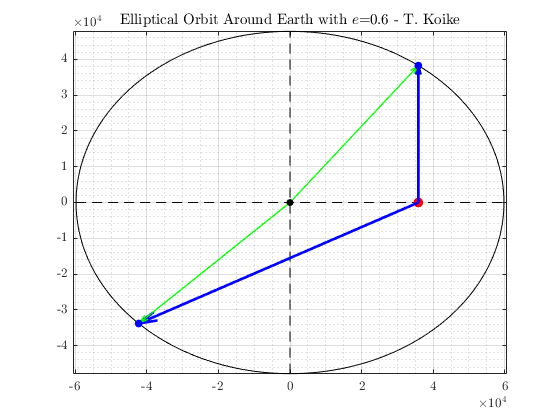

% (d)

% Arrow drawing function
drawArrow = @(x,y,varargin) quiver( x(1),y(1),x(2)-x(1),y(2)-y(1),0, varargin{:} );

% Plotting 
fig1 = figure("Renderer","painters");
hold on; grid on; grid minor; box on; axis equal;
% ylim([-5.5e+4, 5.5e+4]); xlim([-7e+4, 7e+4])
tt = 0:0.01:2*pi;
X = a * cos(tt); Y = b * sin(tt);

% Ellipse
plot(X, Y, '-k')

% Axes 
x_axis = linspace(-a, a, 2^9);
y_axis = linspace(-b, b, 2^9);
plot(x_axis, zeros(size(x_axis)), '--k')
plot(zeros(size(y_axis)), y_axis, '--k')

% Center 
plot(a*e, 0, '.r', 'MarkerSize', 25)

% t0 point
rx_t0 = [a*e, a * cosd(E0)]; ry_t0 = [0, b * sind(E0)];
drawArrow(rx_t0, ry_t0, 'linewidth',2,'Color',[0 0 1]);
rx_t0E = [0, a * cosd(E0)]; ry_t0E = [0, b * sind(E0)];
drawArrow(rx_t0E, ry_t0E, 'linewidth',1,'Color',[0 1 0]);
plot(a * cosd(E0), b * sind(E0), '.b', 'MarkerSize', 20)

% tf point
rx_tf = [a*e, a * cosd(Ef)]; ry_tf = [0, b * sind(Ef)];
drawArrow(rx_tf, ry_tf, 'linewidth',2,'Color',[0 0 1]);
rx_tfE = [0, a * cosd(Ef)]; ry_tfE = [0, b * sind(Ef)];
drawArrow(rx_tfE, ry_tfE, 'linewidth',1,'Color',[0 1 0]);
plot(a * cosd(Ef), b * sind(Ef), '.b', 'MarkerSize', 20)

% Origin
plot(0, 0, '.k', 'MarkerSize', 18)
hold off

title('Elliptical Orbit Around Earth with $e$=0.6 - T. Koike')
saveas(fig1, fullfile(fdir, 'p1_orbitplot.png'));